# Dichotomous Search (İkiye Bölme Arama)

**Exhaustive Search (Tüketici Arama)** yöntemi, tüm deneylerin sonuçlarına bakılmadan önce yürütüldüğü eşzamanlı bir arama yöntemidir. **Dichotomous search (ikili arama)**, **Fibonacci** ve **altın oran (golden section)** yöntemleri gibi, her deneyin sonucunun bir sonraki deneyin konumunu etkilediği **ardışık (sequential)** arama yöntemidir.

Dichotomous arama yönteminde, iki deney olabildiğince birbirine yakın olacak şekilde **belirsizlik aralığının ortasına** yerleştirilir. Bu iki noktadaki amaç fonksiyonunun değerlerine bağlı olarak, belirsizlik aralığının yaklaşık yarısı elimine edilir.

Bu iki noktanın konumları şu şekilde verilir:


$$x_1 =\frac{L_0 }{2}-\delta ,\;\;\;\;\;\;x_2 =\frac{L_0 }{2}+\delta \;$$


Burada $\delta \;$, iki deneyin önemli ölçüde farklı sonuçlar verebilmesini sağlayacak **küçük bir pozitif sayıdır**.

Yeni belirsizlik aralığı şu şekilde bulunur:


$$\frac{L_0 }{2}+\frac{\delta }{2}\;$$


Dichotomous aramanın temel yapı taşı, her adımda mevcut belirsizlik aralığının ortasında **iki deneyin yapılmasıdır**. Her yeni deney çifti, kalan aralığın merkezinde gerçekleştirilir.

Bu şekilde, belirsizlik aralığı her adımda yaklaşık **yarıya iner**.

Belirsizlik aralığının farklı deney çiftlerinden sonra aldığı değerler şu tabloda verilmiştir:

Genel olarak, **n adet deney** (n çift sayı) yapıldıktan sonra nihai belirsizlik aralığı şu şekilde verilir:


$$L_n =\frac{L_{0\;} }{2^{\frac{n}{2}} }+\delta \left(1-\frac{1}{2^{\frac{n}{2}} }\right)$$


### Algoritma

Bir fonksiyon ${f\left(x\right)}^{\prime } \textrm{in}\;\left\lbrack a,b\right\rbrack$ aralığında minimum bulmak istiyoruz.

**Adımlar:**

**1.Parametreleri belirle**

- Aralığı belirle $\left\lbrack a,b\right\rbrack$

- Küçük pozitif sapma $\delta$

- Hassasiyet oranı $\varepsilon$

**2. İki test noktası seç**


$$x_1 =\frac{a+b}{2}-\delta ,\;\;\;\;\;\;x_2 =\frac{a+b}{2}+\delta \;$$


**3. Fonksiyon değerlerini hesapla**


$$f\left(x_1 \right),f\left(x_2 \right)$$


**4. Karşılaştırma yap**

- Eğer $f\left(x_1 \right)<f\left(x_2 \right)$ ise yeni aralık $\left\lbrack a,x_2 \right\rbrack$

- Eğer $f\left(x_1 \right)>f\left(x_2 \right)$ ise yeni aralık $\left\lbrack x_1 ,b\right\rbrack$

**5. Yeni aralık için işlemi tekrarla**

Aralık uzunluğu $\left(b-a\right)<$$\varepsilon$

**6. Sonuç**


$$x^{\prime } =\frac{a+b}{2}$$


## Örnek Problem


$$f\left(x\right)={\left(x-2\right)}^2 +1$$


sonksiyonun minimumu $\left\lbrack 0,4\right\rbrack \;$aralığında

$\delta =0\ldotp 01\;\varepsilon =0\ldotp 05$oalcak şekilde minimum değeri bulun.


$$a=0\;,\;b=4$$



$$\begin{array}{l}
x_1 =2-0\ldotp 01=1\ldotp 99\\
x_{2\;} =2+0\ldotp 01=2\ldotp 01\\
f\left(1\ldotp 99\right)=1\ldotp 001\\
f\left(2\ldotp 01\right)=1\ldotp 001\\
f\left(x_{1\;} \right)=f\left(x_2 \right)\;\textrm{yeni}\;\textrm{aral}\i \mathrm{k}\;\left\lbrack 1\ldotp 99,2\ldotp 01\right\rbrack \;
\end{array}$$


Aralık uzunluğu = 0.02 < 0.05 dur

Sonuç:


$$x^* =2\ldotp 00,f\left(x^* \right)=1\ldotp 00$$


%% Dichotomous Search - Tek Değişkenli Optimizasyon (Iterasyonlu)
clc; clear; close all;

% --- Fonksiyon tanımı ---
f = @(x) (x - 2).^2 + 1;

% --- Başlangıç parametreleri ---
a = 0;                     % Aralık başlangıcı
b = 4;                     % Aralık sonu
delta = 0.01;              % Küçük sapma
epsilon = 0.05;            % Hassasiyet eşiği
iter = 0;                  % İterasyon sayacı

% --- Başlık yazdır ---
fprintf('Iter |    a      |    b      |   x1     |   x2     |  f(x1)   |  f(x2)   | b-a\n');

Iter |    a      |    b      |   x1     |   x2     |  f(x1)   |  f(x2)   | b-a


fprintf('-----+-----------+-----------+----------+----------+----------+----------+------\n');

-----+-----------+-----------+----------+----------+----------+----------+------



% --- Ana döngü ---
while (b - a) > epsilon
    iter = iter + 1;
    x1 = (a + b)/2 - delta;
    x2 = (a + b)/2 + delta;
    
    f1 = f(x1);
    f2 = f(x2);
    
    % Sonuçları tabloya yaz
    fprintf('%3d  | %9.4f | %9.4f | %8.4f | %8.4f | %8.4f | %8.4f | %.4f\n', ...
            iter, a, b, x1, x2, f1, f2, (b - a));

    % Karar bloğu
    if f1 < f2
        b = x2;
    else
        a = x1;
    end
end

  1  |    0.0000 |    4.0000 |   1.9900 |   2.0100 |   1.0001 |   1.0001 | 4.0000
  2  |    1.9900 |    4.0000 |   2.9850 |   3.0050 |   1.9702 |   2.0100 | 2.0100
  3  |    1.9900 |    3.0050 |   2.4875 |   2.5075 |   1.2377 |   1.2576 | 1.0150
  4  |    1.9900 |    2.5075 |   2.2388 |   2.2587 |   1.0570 |   1.0670 | 0.5175
  5  |    1.9900 |    2.2587 |   2.1144 |   2.1344 |   1.0131 |   1.0181 | 0.2687
  6  |    1.9900 |    2.1344 |   2.0522 |   2.0722 |   1.0027 |   1.0052 | 0.1444
  7  |    1.9900 |    2.0722 |   2.0211 |   2.0411 |   1.0004 |   1.0017 | 0.0822
  8  |    1.9900 |    2.0411 |   2.0055 |   2.0255 |   1.0000 |   1.0007 | 0.0511



% --- Sonuç ---
x_opt = (a + b)/2;
f_opt = f(x_opt);

fprintf('\n---------------------------------------------\n');


---------------------------------------------


fprintf('Minimum f(%.4f) = %.4f (Iterasyon: %d)\n', x_opt, f_opt, iter);

Minimum f(2.0078) = 1.0001 (Iterasyon: 8)


fprintf('---------------------------------------------\n');

---------------------------------------------



% --- Görselleştirme ---
x = linspace(0,4,200);
plot(x,f(x),'LineWidth',1.5);
hold on;
plot(x_opt,f_opt,'r*','MarkerSize',10,'LineWidth',2);
title('Dichotomous Search');
xlabel('x'); ylabel('f(x)');
legend('f(x)','Minimum Nokta');
grid on;


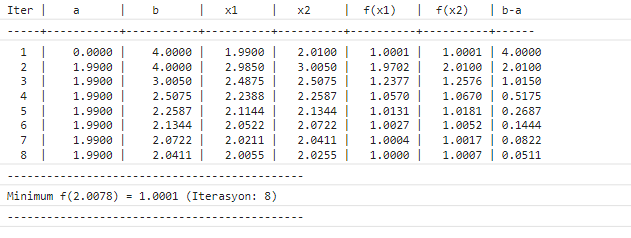

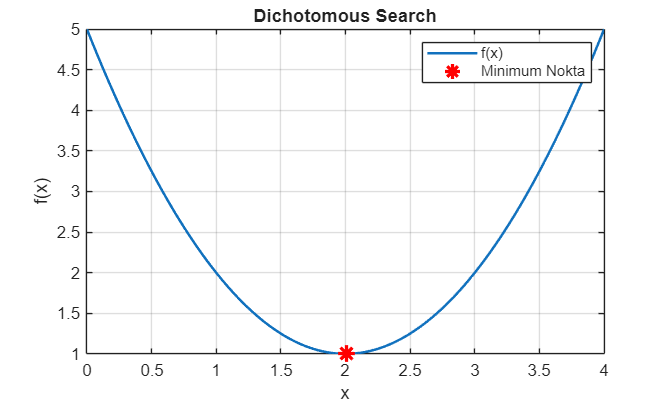


$$\begin{array}{l}
f\left(x,y\right)={\left(x-1\right)}^{2\;} +{\left(y-2\right)}^2 \\
x\in \left\lbrack 0,2\right\rbrack \;,y\in \left\lbrack 0,3\right\rbrack 
\end{array}$$



%% Coordinate-wise Dichotomous Search (2D) - Çözüm
clc; clear; close all;

% Fonksiyon
f = @(x, y) (x - 1).^2 + (y - 2).^2;

% Parametreler
a_x = 0; b_x = 2;
a_y = 0; b_y = 3;
delta   = 0.01;     % küçük sapma
epsilon = 0.05;     % durdurma eşiği
max_iter = 100;

% Başlık
fprintf('Iter | [ax,bx] len | [ay,by] len | x_mid   | y_mid   | f(x_mid,y_mid)\n');

Iter | [ax,bx] len | [ay,by] len | x_mid   | y_mid   | f(x_mid,y_mid)


fprintf('-----+-------------+-------------+---------+---------+----------------\n');

-----+-------------+-------------+---------+---------+----------------



iter = 0;
while ((b_x - a_x) > epsilon) || ((b_y - a_y) > epsilon)
    iter = iter + 1;

    % X boyunca dichotomous
    xmid = (a_x + b_x)/2;
    ymid = (a_y + b_y)/2;

    x1 = xmid - delta;  x2 = xmid + delta;
    f1 = f(x1, ymid);   f2 = f(x2, ymid);

    if f1 < f2
        b_x = x2;
    else
        a_x = x1;
    end

    % Y boyunca dichotomous
    xmid = (a_x + b_x)/2;
    ymid = (a_y + b_y)/2;

    y1 = ymid - delta;  y2 = ymid + delta;
    g1 = f(xmid, y1);   g2 = f(xmid, y2);

    if g1 < g2
        b_y = y2;
    else
        a_y = y1;
    end

    % Günlük
    xmid = (a_x + b_x)/2;
    ymid = (a_y + b_y)/2;
    fprintf('%3d  | %11.5f | %11.5f | %7.4f | %7.4f | %14.6f\n', ...
            iter, (b_x - a_x), (b_y - a_y), xmid, ymid, f(xmid, ymid));

    if iter >= max_iter
        warning('Max iterasyona ulaşıldı.'); break;
    end
end

  1  |     1.01000 |     1.51000 |  1.4950 |  2.2450 |       0.305050
  2  |     0.51500 |     0.76500 |  1.2475 |  1.8725 |       0.077513
  3  |     0.26750 |     0.39250 |  1.1238 |  2.0587 |       0.018766
  4  |     0.14375 |     0.20625 |  1.0619 |  1.9656 |       0.005010
  5  |     0.08188 |     0.11312 |  1.0309 |  2.0122 |       0.001106
  6  |     0.05094 |     0.06656 |  1.0155 |  1.9889 |       0.000362
  7  |     0.03547 |     0.04328 |  1.0077 |  2.0005 |       0.000060



% Sonuç
x_opt = (a_x + b_x)/2;
y_opt = (a_y + b_y)/2;
f_opt = f(x_opt, y_opt);

fprintf('\nSONUC: x*=%.6f, y*=%.6f, f=%.9f, iter=%d\n', x_opt, y_opt, f_opt, iter);


SONUC: x*=1.007734, y*=2.000547, f=0.000060120, iter=7


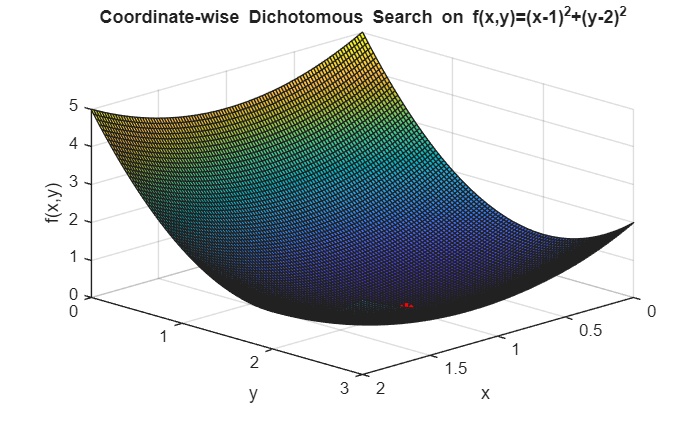


% Görsel
[X, Y] = meshgrid(0:0.02:2, 0:0.03:3);
F = f(X,Y);
figure; surf(X, Y, F); hold on;
plot3(x_opt, y_opt, f_opt, 'r*', 'MarkerSize', 10, 'LineWidth', 2);
title('Coordinate-wise Dichotomous Search on f(x,y)=(x-1)^2+(y-2)^2');
xlabel('x'); ylabel('y'); zlabel('f(x,y)'); grid on; view(135, 30);